# The Spectrum of the JL operator

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev. For this example, we will define two different graphs, one with the uniform discretization and one with the Chebyshev discretization for the purpose of comparing the spectrum of the JL operator defined on each graph.

tag='dumbbell';
Phi = quantumGraphFromTemplate(tag,'discretization','Chebyshev','nX',32);
PhiUni = quantumGraphFromTemplate(tag,'nX',128);

## Spectrum of JL using Chebyshev points

First, we must generate solutions to the stationary problem.

diagramNumber=eigenfunctionsSaveData(Phi,tag,4,1,0);

Saved to directory data\dumbbell\020.
Run number is 20.


options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\020\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\020\branch002.
No branching bifurcations found.


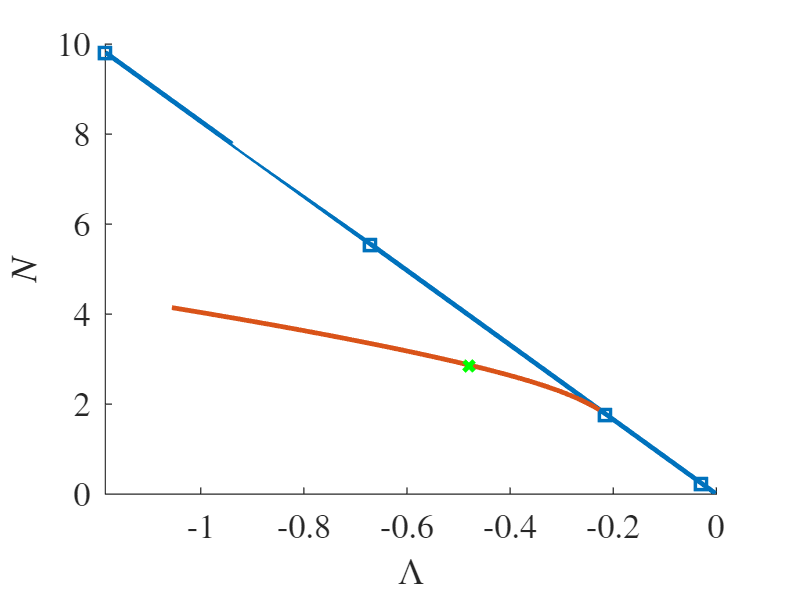

bifurcationDiagram(tag,diagramNumber)
hold on
plot(-0.477919,2.86432,'gx');

Then, load the solution.

u = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.010'));
muvec = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'LambdaVec'));
mu = muvec(10);

Define the JL operator then find its eigenvalues.

fcns = getGraphFcns(Phi);
JL = fcns.H(u,mu);

## Spectrum of JL using uniform points

We again begin with generating solutions to the stationary problem.

diagramNumber=eigenfunctionsSaveData(PhiUni,tag,4,1,0);

Saved to directory data\dumbbell\021.
Run number is 21.


options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\021\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\021\branch002.
No branching bifurcations found.


Instead of just simply loading the solution, Newton's method must now be used to interpolate the data in order to ensure that it finds the solution that corresponds to the same mu (and thus same stationary problem) that was used earlier.

uguess = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.010'));

fcnsU = getGraphFcns(PhiUni);
ff=@(z) fcnsU.f(z,mu);
fM=@(z) fcnsU.fLinMatrix(z,mu);
tol=1e-8;
uUni = solveNewton(uguess,ff,fM,tol);

Define the JL operator then find its eigenvalues.

JLUni = fcnsU.H(uUni,mu);

## Comparing JL spectrums from different discretizations

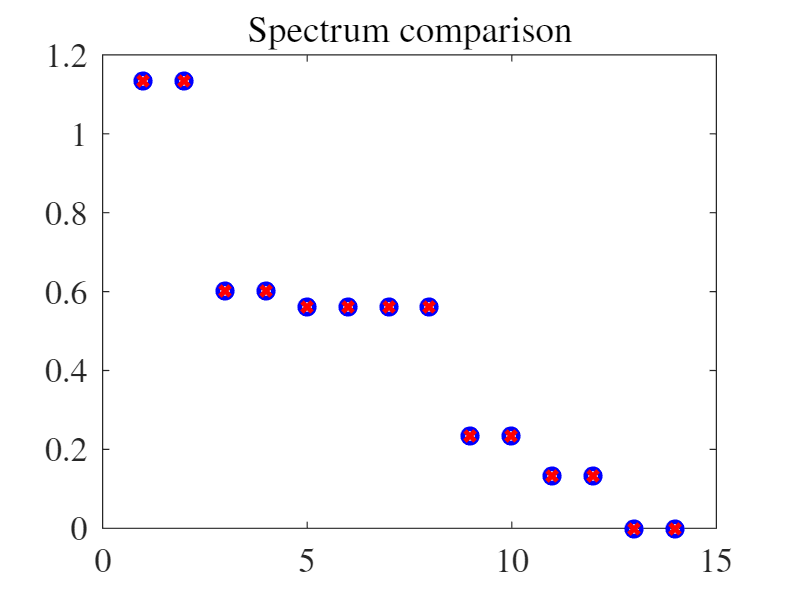

nEvals = 14;
[V,lambda] = eigsJL(Phi,JL,nEvals);
[VUni,lambdaUni] = eigsJL(PhiUni,JLUni,nEvals);
l1 = lambdaUni(1);
l2 = lambdaUni(2);
lambdaUni(2)=l1;
lambdaUni(1)=l2;
l5 = lambdaUni(5);
l6 = lambdaUni(6);
l7 = lambdaUni(7);
l8 = lambdaUni(8);
lambdaUni(5) = l7;
lambdaUni(6) = l6;
lambdaUni(7) = l8;
lambdaUni(8) = l5;
l9 = lambdaUni(9);
l10 = lambdaUni(10);
lambdaUni(9)=l10;
lambdaUni(10)=l9;
l11 = lambdaUni(11);
l12 = lambdaUni(12);
lambdaUni(11)=l12;
lambdaUni(12)=l11;

figure
plot(abs(lambda),'bo')
hold on
plot(abs(lambdaUni),'rx')
title('Spectrum comparison')

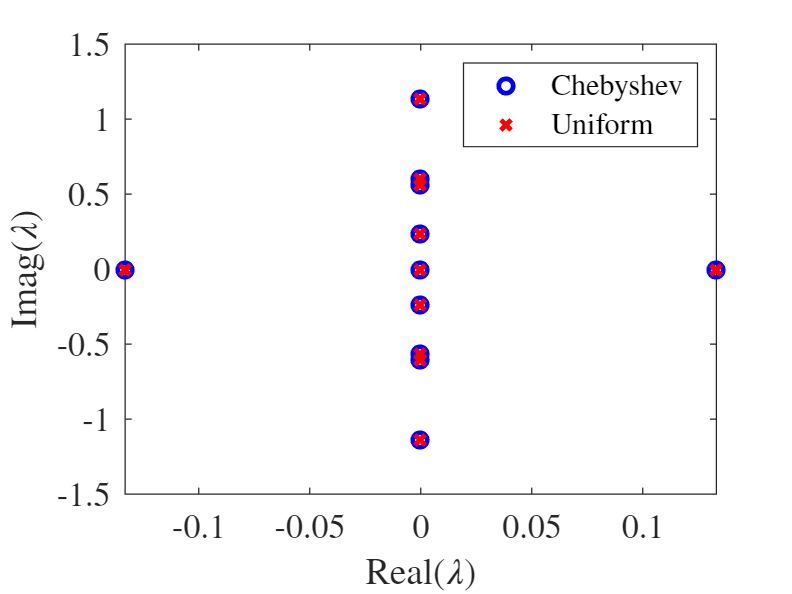


figure
plot(real(lambda),imag(lambda),'bo')
hold on
plot(real(lambdaUni),imag(lambdaUni),'rx')
xlabel('Real($\lambda$)')
ylabel('Imag($\lambda$)')
legend('Chebyshev','Uniform')

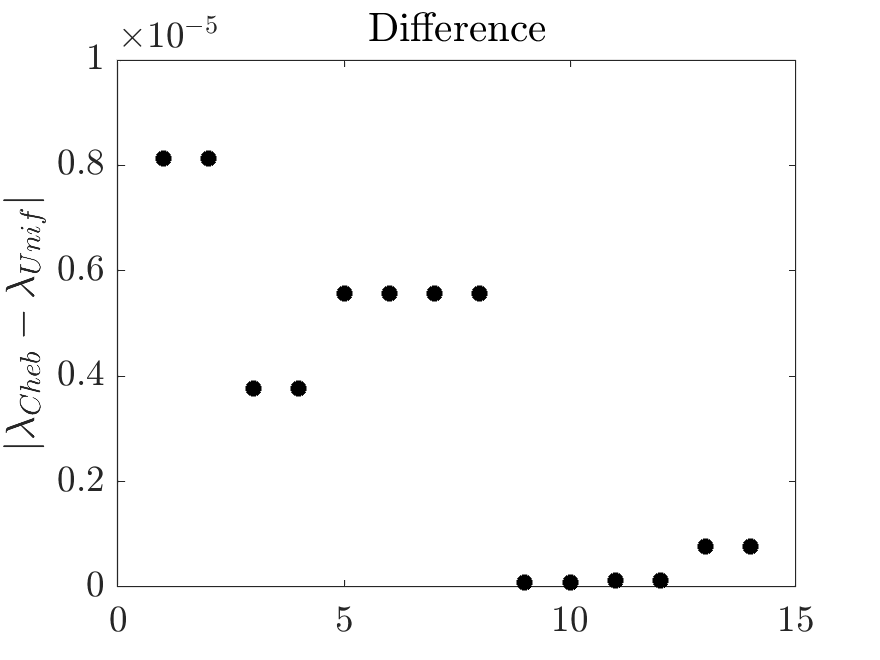


figure
plot(abs(lambda-lambdaUni),'k*')
title('Difference')
ylabel('$|\lambda_{Cheb}-\lambda_{Unif}|$')

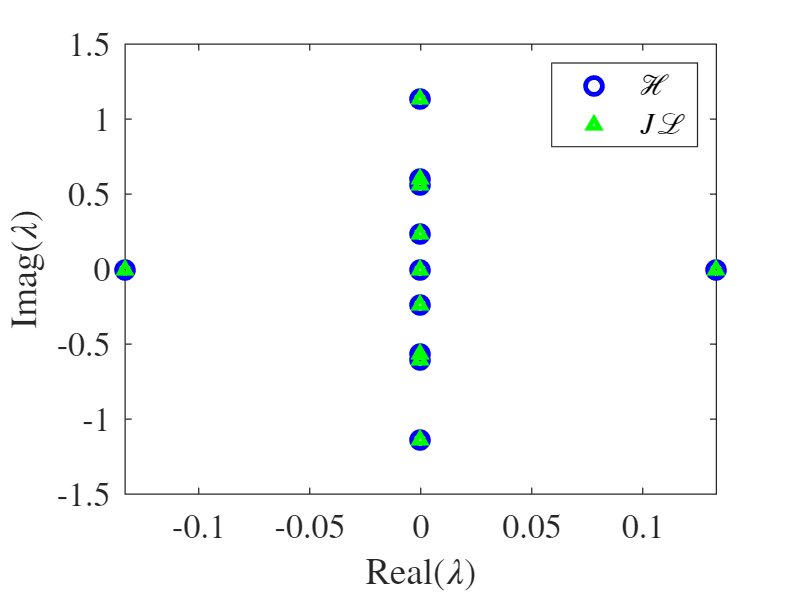

fcns = getGraphFcns(Phi);
JL = fcns.JL(u,mu);
H = fcns.H(u,mu);
[V,lambda] = eigsJL(Phi,JL,nEvals);
[VH,lambdaH] = eigsJL(Phi,H,nEvals);


figure
plot(real(lambdaH),imag(lambdaH),'bo','MarkerSize',7)
hold on
plot(real(lambda),imag(lambda),'g^','MarkerSize',4)
xlabel('Real($\lambda$)')
ylabel('Imag($\lambda$)')
legend('$\mathcal{H}$','$J\mathcal{L}$')